# Exercise 4

## Using a Particle Filter

### Abouth This Exercise

You previously saw the effectiveness of using a Kalman filter when dealing with uncertainty to solve the localization problem. However, you must remember that the Kalman filter always assumes Gaussian distributions for the belief in the state and the noise in both the measurements and processes. When we initialized the Kalman filter with a guess, we were implying an initial Guassian distribution of possible states. However, if we truly have no prior information on where the robot is in the map, we might rather start with a uniform distribution, where the robot is as likely to be in the corner as it is the center. We may want to simulate many possibilities of where the robot is given this distribution and propagate the ones that best match the sensory data. Simulating these 'many worlds' is the idea behind what is called the particle filter, where each particle represents one possible robot state.

Here, you will first develop the particle filter algorithm. The concepts underlying both methods are similar: you first predict the robot movements according to the process model (which are the kinematic equations) and then update the likelihood of those predictions given how good the actual measurements match the predicted, or expected, measurements. While the Kalman filter applied these concepts to a single Gaussian distribution, the particle filter applies it to every particle, where the particles that more likely match the sensory data are more likely to propagate. This process is similar to evolution, where particles that are 'more fit' will likely duplicate and others that are 'less fit' will die out.

**By the end of this exercise, you'll be able to: **

- **Simulate the likely poses of a robot using the particle filter algorithm. **

### Particle Initialization

Just like the Kalman filter, the particle filter is an iterative algorithm that makes predictions based on the previous solution and updates the predictions according to the measurements taken. Therefore, the first iteration needs to have some initial guess of the distribution of particles. In general, we only know that the robot is located somewhere in the map, so we'll create a function that samples M particles according to a uniform distribution within the map.

[► Complete the getInitParticles function](matlab:open('./getInitParticles.mlx')) 

Once it is complete, set the inputs and call your function below.

M = 30; %Change value here (10-100)
map = load('MAP102-N2.txt');
stateDim = 2; 

**Complete the code below.**

X = getInitParticles(M,map,stateDim);  % call getInitParticles here

This will plot the result, change the slider to see how the sampling of particles works. You can see with just two dimensions to cover, even having 100 particles leaves gaps in the coverage.

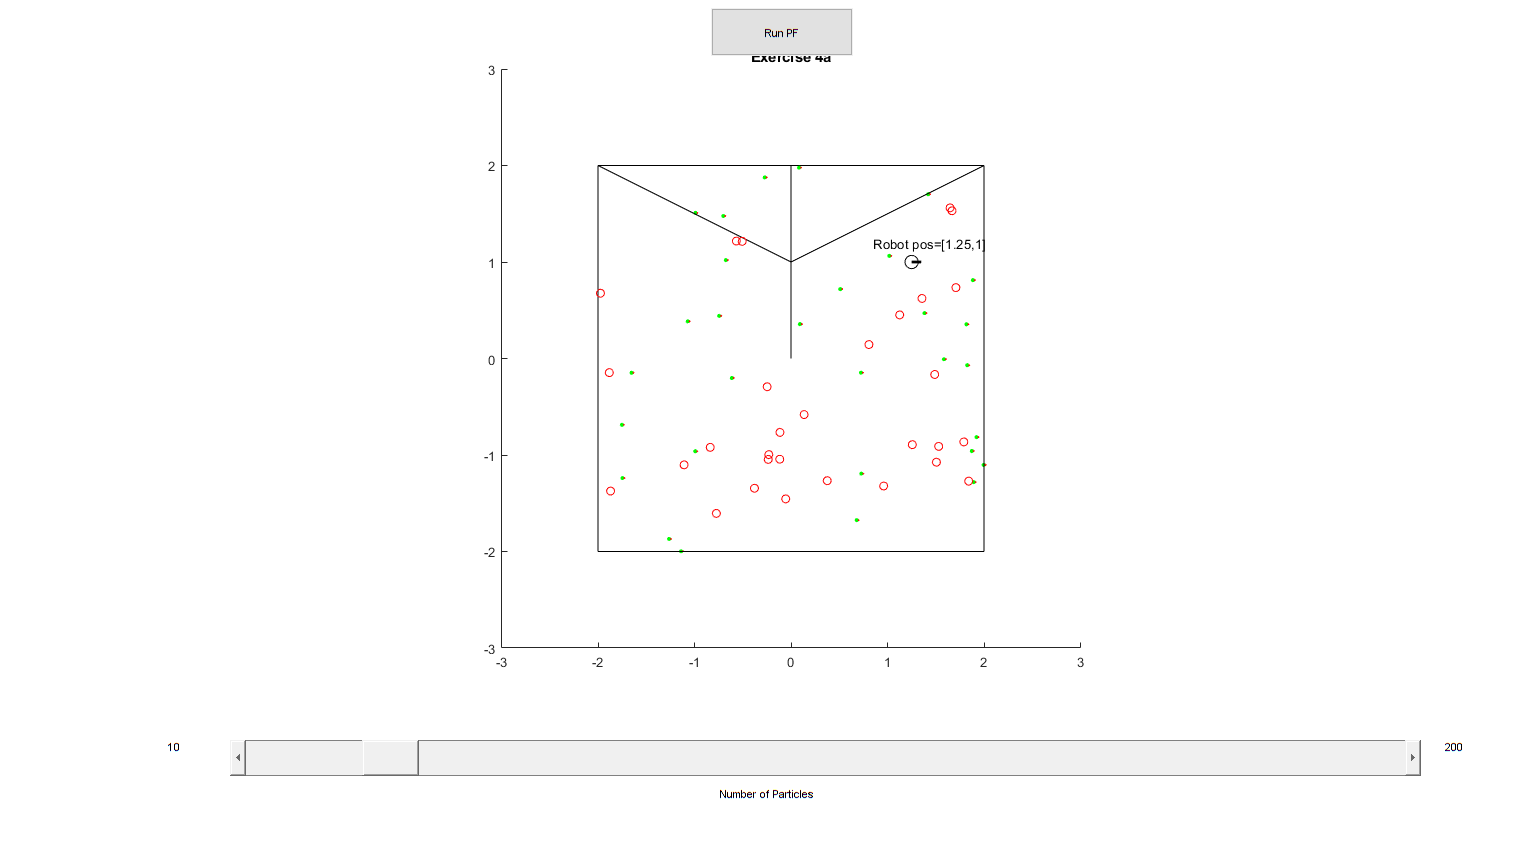

plot_title = "Exercise 4a"; 
plotParticles(map, X, plot_title);

### The Particle Filter for a Stationary Robot

The particle filter is similar to the Kalman filter, where we make predictions to the state of the system given the inputs and then update the state according to the measurements. Instead of performing these steps on one Gaussian distribution that represents the belief on the robot state, we perform these steps on the particles which we sample to hopefully best represent the belief of the robot state. The particle filter requires an input set of particles, a process model (with inputs), and a measurement model (with true measurements).

For the prediction step, you need to move each particle according to the process model and current input, which generally has some noise term associated with it. Then, find the measurement expected for each particle and calculate how likely that particle matches the true position given the actual measurement. This likelihood for each particle is represented by the weight vector $w$.

For the update step, resample the particles according to the weights $w$. This resampling has the effect of copying more likely particles in place of less likely particles. Thus you build a new set of particles that will be the input into the next cycle with the next input and measurement.

[► Complete the PF function](matlab:open('./PF.mlx'))

### Test 1 step of the Particle Filter

The particle filter, like the Extended Kalman filter, has a lot of inputs organized into a struct which we'll call pfArgs. Here we have initialized those arguments and then call PF to test your function. Carefully go over all of these parameter and use it as a guide for setting parameters in future exercises.

- Set the number of particles

M = 30;

- Single control input 

pfArgs.u = [0;0];%Stationary

- Initial robot position

robotXY = [1.25;1];
pfArgs.stateDim = length(robotXY); % Needed to distiguish between holonomic and non-holonomic
pfArgs.startingTheta = 0; 

- Load the map we will use for this course

pfArgs.map = load('MAP103M1.txt');

- Get initial particle set using the getInitParticles

pfArgs.X = getInitParticles(M,pfArgs.map,pfArgs.stateDim, pfArgs.startingTheta);

- Set up measurment for LIDAR, The function measFunc uses ExpectedMeasurementLidar by default, in later exercises we will set a parameter to use a different sensor.

pfArgs.alpha = [pi, pi/2, 0, -pi/2]';
pfArgs.Q = diag(0.1*ones(1,length(pfArgs.alpha)));
pfArgs.maxRange = 4;
pfArgs.measFunc = @measFunc; 

- Actual measurement

pfArgs.meas = feval(pfArgs.measFunc,[robotXY; 0],pfArgs);

- Set up the kinematic function and inputs. procFuncHolonomic returns the next state given the current state, current control, dt, and process noise covariance matrix $R$.

pfArgs.procFunc = @procFuncHolonomic;
pfArgs.stateDim = length(robotXY);
pfArgs.R = diag([100, 100]);
pfArgs.dt = 0.01;

-  Now that all of the arguments are set, use the PF function for one step.

[Xnext, w] = PF(pfArgs);

- This plots the input particle set in blue and the output particle set in red with some noise added to see particles that were resampled more than once (particles with higher likelyhood have been selected multiple times). The button reruns this section so you can see how the random sampling affects the particle filter.

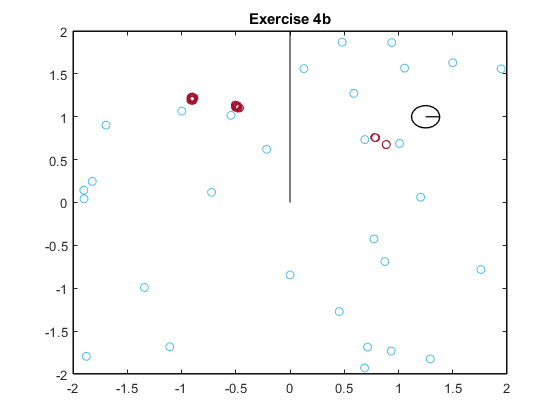

plot_title = "Exercise 4b";  
plotPFstep(pfArgs, Xnext, robotXY, plot_title);

### Particle Filter for Stationary Robot

The function plotPF takes in the pfArgs, a set of control inputs, and the starting position (or pose for the differential drive version) of the robot and both simulates the robot and runs your particle filter. It plots the result in a new figure where you can reinitialize the starting particle set with a slider that sets the number of particles, and then hit the run button which animates the simulation and the particle filter.

For this example, set a matrix size 2-by-N of zeros to be the control input. This will simulate a stationary robot that takes N measurements (you can choose N). Hitting the run button will resimulate the measurements and rerun the particle filter for the same initial particle set. You'll see sometimes the particle filter converges on the true position and sometimes it converges on the other position that would receive the same sensory information.

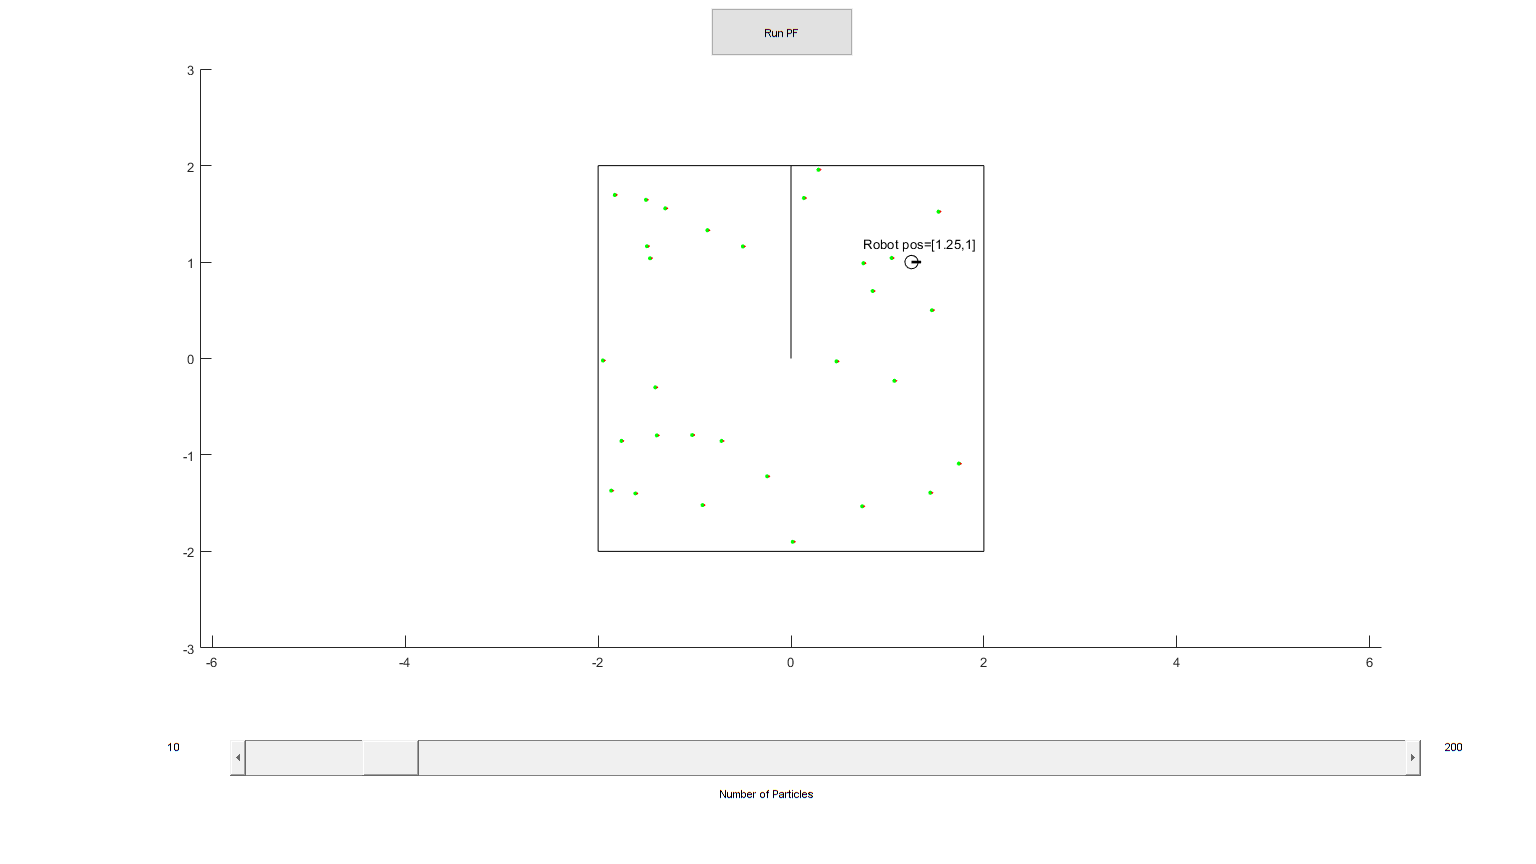

u = zeros(2,300);

plotPF(pfArgs,u,robotXY)

### Finished!

Congrats on simulating a particle filter! What you have done is created a bunch of simulations of the robot and tested those simulations against the actual data. But how do you now combine the results of these simulations into a single estimate of the state of the robot? The answer is not straightforward, as is probably clear in this exercise. We will explore how to estimate a single state from a particle set in the next exercise.